clc; clear; clf, close all;

typeI = 'Intermedio';
Folders.FolderCodes = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Codes\';
Folders.FolderCodesTests = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Codes\Tests\';
Folders.FolderCodesFunc = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Codes\Functions\';
Folders.FolderNGI = ['D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\', typeI, '\NGI\'];
Folders.FolderGT = ['D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\', typeI, '\IonogramImagesGT\'];


% Random file
fileList = dir(fullfile(Folders.FolderNGI, '/*.ngi'));
% randomIdx = randi(length(fileList), 1, 1);
% zippedDataFrame = fileList(randomIdx).name;

clear i
for i = 1:length(fileList)
    zippedDataFrame = fileList(i).name;

    % zippedDataFrame = 'varJM91J_2021249000303.ngi';% 'varJM91J_2021249181804.ngi';

    % Get data
    cd(Folders.FolderCodesFunc)
    IonogramData = GettingRelevantData(zippedDataFrame, Folders);

    % CustomPlot(IonogramData, IonogramData.totalpowerData)

    % Test Glob Thresh
    cd(Folders.FolderCodesTests)
    % TestingThresh
    [OMode, XMode, TPower]  = testingvar_(IonogramData, Folders, zippedDataFrame);

    % figure, imagesc(flip(TPower.imgDen)), colorbar
    % figure, imagesc(flip(TPower.imgLaplacian)), colorbar
    % figure, imagesc(flip(TPower.imgOutliners)), colorbar
    % figure, imagesc(flip(TPower.imgThresh)), colorbar

    % Precision = TPower.TP/(TPower.TP+TPower.FP)
    % Recall = TPower.TP/(TPower.TP+TPower.FN)

    cd(Folders.FolderCodesFunc)
    clear T_1 Precision_T1 Recall_T1 varFolder TP FP FN TN

    T_1 = 5:round(max(TPower.imgDen(:)))-5;
    for i = 1:length(T_1)
        % Thresholding global test 1 -- Intensity value reduction
        imgThresh_T1 = ThreshImg_Global(TPower.imgDen, T_1(i));
        [TP_TestTh1, FP_TestTh1, FN_TestTh1, TN_TestTh1] = IoUsimple(imgThresh_T1, TPower.iGT);

        TP(i) = TP_TestTh1; FP(i) = FP_TestTh1; FN(i) = FN_TestTh1; TN(i) = TN_TestTh1;

        Precision_T1(i) = TP_TestTh1/(TP_TestTh1 + FP_TestTh1);
        Recall_T1(i) = TP_TestTh1/(TP_TestTh1 + FN_TestTh1);
    end
    T_1 = T_1';  Precision_T1 =  Precision_T1'; Recall_T1 = Recall_T1'; TP = TP'; FP = FP'; FN = FN'; TN = TN';
    varNames = {'Threshold', 'Precision', 'Recall', 'TP', 'FP', 'FN', 'TN'};
    Test_1 = table(T_1, Precision_T1, Recall_T1, TP, FP, FN, TN, 'VariableNames',varNames);

    % Best thresh
    Best_Thresh_1_idx = find(Precision_T1 == max(Precision_T1));
    Best_Thresh_Test1_Precision = T_1(double(Best_Thresh_1_idx));
    Best_Test1_Precision = Precision_T1(double(Best_Thresh_1_idx));

    clear T_2 Precision_T2 Recall_T2 TP FP FN TN i T_2_var
    T_2_var = unique(round(TPower.imgOutliners(:), 2));
    T_2 = T_2_var(2:2:length(T_2_var)-10);
    for i = 1:length(T_2)

        % Thresholding global test 2 -- Outliners
        imgThresh_T2 = ThreshImg_Global(TPower.imgOutliners, T_2(i));
        [TP_TestTh2, FP_TestTh2, FN_TestTh2, TN_TestTh2] = IoUsimple(imgThresh_T2, TPower.iGT);

        TP(i) = TP_TestTh2; FP(i) = FP_TestTh2; FN(i) = FN_TestTh2; TN(i) = TN_TestTh2;

        Precision_T2(i) = TP_TestTh2/(TP_TestTh2 + FP_TestTh2);
        Recall_T2(i) = TP_TestTh2/(TP_TestTh2 + FN_TestTh2);
    end
    Precision_T2 =  Precision_T2'; Recall_T2 = Recall_T2'; TP = TP'; FP = FP'; FN = FN'; TN = TN';
    varNames = {'Threshold', 'Precision', 'Recall', 'TP', 'FP', 'FN', 'TN'};
    Test_2 = table(T_2, Precision_T2, Recall_T2, TP, FP, FN, TN, 'VariableNames',varNames);

    % Best Trhesh
    % Best_Thresh_Test2_Precision = find(unique(Precision_T2) == max(Precision_T2));
    Best_Thresh_2_idx = find(Precision_T2 == max(Precision_T2));
    Best_Thresh_Test2_Precision = T_2(double(Best_Thresh_2_idx));
    Best_Test2_Precision = Precision_T2(double(Best_Thresh_2_idx));

    clear T_1 Precision_T1 Recall_T1 T_2 Precision_T2 Recall_T2 TP FP FN TN imgThresh_T1 TP_TestTh1 FP_TestTh1 ...
        FN_TestTh1 TN_TestTh1 imgThresh_T2 TP_TestTh2 FP_TestTh2 FN_TestTh2 TN_TestTh2 i varNames

    %varmat = [zippedDataFrame, 'Test_1_'];

    varNames = {'Ionogram name', 'Best Thresh - T1', 'Best Thresh - T2'};
    varzipdata = strrep(zippedDataFrame,'.ngi','');
    Best_Thresh = table(string(varzipdata), Best_Thresh_Test1_Precision, Best_Thresh_Test2_Precision, 'VariableNames',varNames);


    varFolder = ['D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\', typeI, '\Metrics_Tests\'];

    cd(varFolder)

    save([varzipdata, '_Test_Thresholds.mat'], 'Test_1', 'Test_2')
    save([varzipdata, '_Best_Thresh.mat'], 'Best_Thresh')

    clear varzipdata varFolder varNames Best_Thresh_Test1_Precision Best_Thresh_Test2_Precision
    %cd(Folders.FolderCodesFunc)

    % Test laplacian thresh
end
clear i Test_1 Test_2 Best_Thresh

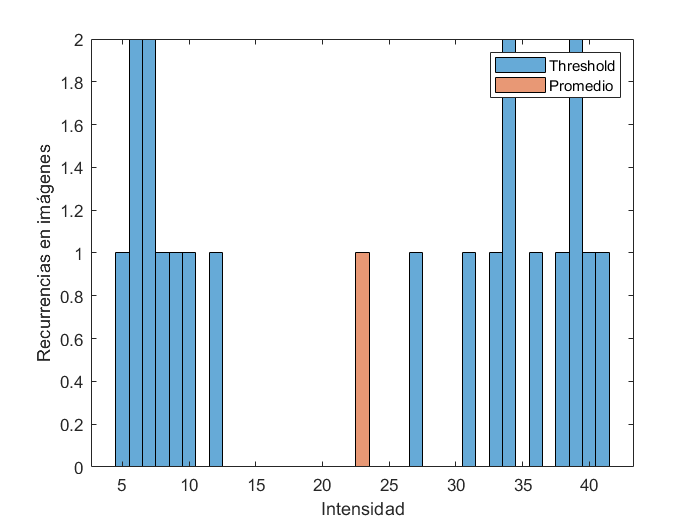

clear i varzipdata a_


for i = 1:length(fileList)
    a_ = fileList(i).name;
    varzipdata = strrep(a_,'.ngi','');
    load([varzipdata, '_Best_Thresh.mat'])

    b_(i) = Best_Thresh.("Ionogram name");
    c_(i) = Best_Thresh.("Best Thresh - T1");
    d_(i) = Best_Thresh.("Best Thresh - T2");

end
b_ = b_'; c_ = c_'; d_ = d_';

varNames = {'Ionogram name', 'Best Thresh - T1', 'Best Thresh - T2'};
ThreshPlot = table(b_, c_, d_, 'VariableNames',varNames);

clear i varzipdata varNames Best_Thresh a_ b_ c_ d_

histogram(ThreshPlot.("Best Thresh - T1")); hold on
histogram(mean(ThreshPlot.("Best Thresh - T1")))
ylabel("Recurrencias en imágenes")
xlabel("Intensidad")
legend('Threshold', 'Promedio'), hold off

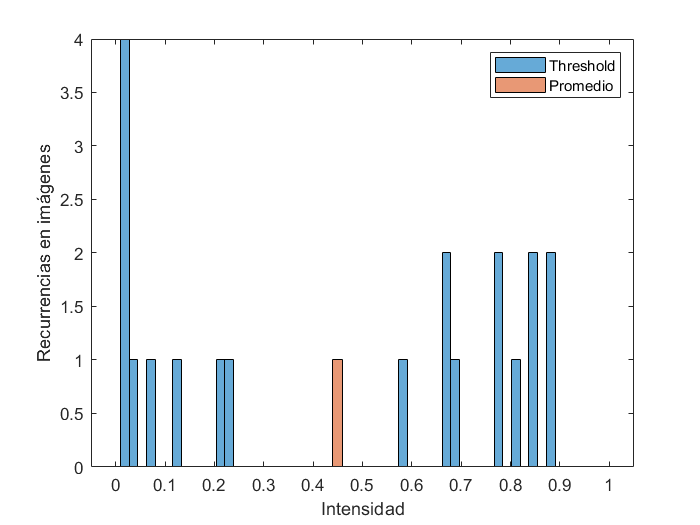

% boxplot(ThreshPlot.("Best Thresh - T1"))

histogram(ThreshPlot.("Best Thresh - T2"), 50); hold on
histogram(mean(ThreshPlot.("Best Thresh - T2")), 50)
ylabel("Recurrencias en imágenes")
xlabel("Intensidad")
legend('Threshold', 'Promedio'), hold off

% boxplot(ThreshPlot.("Best Thresh - T2"))

%cd(Folders.FolderCodesFunc)

% FIgure 9.11 Gonzales

% sembrar semila hasta rellenar todos los pixeles  de esa región, medimos el area (a<n -> eliminamos esa region)

% fields = fieldnames(Images)
% var_ = struct2cell(Images);
% imgsVar_ = cell2mat(var_(1));
%
% for i = 2:size(var_, 1)
%     %imgsVar_ = cat(3, imgsVar_, string(fields(i)));
%     imgsVar_ = cat(3, imgsVar_, cell2mat(var_(i)));
% end


% montage(flip(imgsVar_(:,:,(2:end))))
% title("imgDen -- imgLaplacian -- Outliners -- imgThresh")

% Dilate
% SE = strel('rectangle',[20 20]); % lo cambie de 3x3 a 4x6 para que se parezca al paper
% imgDil = imdilate(Images.imgThresh_totalp, SE);
%
% iIonCCL = bwlabel(imgDil);
% figure, imagesc(flip(iIonCCL))

% Median filter

% J = medfilt2(iIonCCL, [20, 20]);
% figure, imagesc(flip(J))
% figure, imagesc(flip(Images.imgThresh_totalp))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% img = Images.imgThresh_totalp;
% [~,threshold] = edge(img,'sobel');
% fudgeFactor = 0.5;
% BWs = edge(img,'sobel',threshold * fudgeFactor);
%
% imagesc(BWs)
% title('Binary Gradient Mask')
%
% se90 = strel('line',3,90);
% se0 = strel('line',3,0);
%
%
% BWsdil = imdilate(BWs,[se90 se0]);
% imagesc(BWsdil)
% title('Dilated Gradient Mask')
%
%
% BWdfill = imfill(BWsdil,'holes');
% imagesc(BWdfill)
% title('Binary Image with Filled Holes')
%
%
% BWnobord = imclearborder(BWdfill,4);
% imagesc(BWnobord)
% title('Cleared Border Image')
%
%
% seD = strel('diamond',1);
% BWfinal = imerode(BWnobord,seD);
% BWfinal = imerode(BWfinal,seD);
% imagesc(BWfinal)
% title('Segmented Image');
%
% imagesc(labeloverlay(double(img),BWfinal))
% title('Mask Over Original Image')
%
%
% BWoutline = bwperim(BWfinal);
% Segout = double(img);
% Segout(BWoutline) = 255;
% imagesc(Segout)
% title('Outlined Original Image')


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cd(Folders.FolderCodesFunc)


% figure, CustomPlot(IonogramData, Images.imgLaplacian_Omode)
% CustomPlot(IonogramData, IonogramData.OModepowerData)
% CustomPlot(IonogramData, Images.imgDen_Xmode)
% CustomPlot(IonogramData, IonogramData.XModepowerData)
% CustomPlot(IonogramData, Images.imgDen_totalp)
% CustomPlot(IonogramData, IonogramData.totalpowerData)

% [NoCorrectos, correctos] = IoUsimple(Images.imgThresh_totalp, Images.iGT);

%cd(Folders.FolderCodesTests)

% Test Freq filt
%TestingFreqFilt

